vehicleData=load("C:\Govind1\vehicleDataset_Multi_Final.mat")

vehicleData = struct with fields:
    vehicleDataset_Multi_Final: [3358×4 table]


vehicleData=vehicleData.vehicleDataset_Multi_Final;
vehicleData=vehicleData(:,1:3)

vehicleData = 3358×3 table
                 imageFilename                     Bike        Glowing_Light
    _______________________________________    ____________    _____________

    "C:\Govind\training_data1\v111_001.png"    {1×4 double}    {0×0 double} 
    "C:\Govind\training_data1\v111_004.png"    {1×4 double}    {0×0 double} 
    "C:\Govind\training_data1\v111_007.png"    {1×4 double}    {0×0 double} 
    "C:\Govind\training_data1\v111_010.png"    {1×4 double}    {0×0 double} 
    "C:\Govind\training_data1\v111_013.png"    {1×4 double}    {0×0 double} 
    "C:\Govind\training_data1\v111_016.png"    {1×4 double}    {0×0 double} 
    "C:\Govind\training_data1\v111_019.png"    {1×4 double}    {0×0 double} 
    "C:\Govind\training_data1\v111_022.png"    {1×4 double}    {0×0 double} 
    "C:\Govind\training_data1\v111_025.png"    {1×4 double}    {0×0 double} 
    "C:\Govind\training

rng(0);
shuffledIndices = randperm(height(vehicleData));
idx = floor(0.98 * length(shuffledIndices));
trainingData = vehicleData(shuffledIndices(1:idx), :);
testData = vehicleData(shuffledIndices(idx+1:end), :);

filterSize = [3 3]; 

middleLayers = [
    convolution2dLayer(filterSize, 16, 'Padding', 1,'Name','conv_1',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN1')
    reluLayer('Name','relu_1')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool1')
    convolution2dLayer(filterSize, 32, 'Padding', 1,'Name', 'conv_2',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN2')
    reluLayer('Name','relu_2')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool2')
    convolution2dLayer(filterSize, 64, 'Padding', 1,'Name','conv_3',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN3')
    reluLayer('Name','relu_3')
    maxPooling2dLayer(2, 'Stride',2,'Name','maxpool3')
    convolution2dLayer(filterSize, 128, 'Padding', 1,'Name','conv_4',...
    'WeightsInitializer','narrow-normal')
    batchNormalizationLayer('Name','BN4')
    reluLayer('Name','relu_4')
    ];


inputLayer = imageInputLayer([448 448 3],'Name','input','Normalization','none');

lgraph = layerGraph([inputLayer; middleLayers]);

Compute number of Classes based on Input data.

numClasses = size(trainingData,2)-1;

imdsTrain = imageDatastore(trainingData{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingData(:,2:end));
% % bxdsTrain2 = boxLabelDatastore(trainingData{:,'Var3'});
% % bxdsTrain3 = boxLabelDatastore(trainingData{:,'Var4'});
%  
% 
trainingDatastore=combine(imdsTrain,bldsTrain);
numAnchors = 4;
[anchorBoxes, meanIoU] = estimateAnchorBoxes(trainingDatastore, numAnchors)

%anchorBoxes(1,1)=35
%anchorBoxes(1,2)=37
%anchorBoxes(4,1)=305
%anchorBoxes(4,2)=201
%anchorBoxes

lgraph = yolov2Layers([1077 1912 3],numClasses,anchorBoxes,lgraph,'relu_4');

options = trainingOptions('sgdm', ...
        'InitialLearnRate',0.001, ...
        'Verbose',true,'MiniBatchSize',3,'MaxEpochs',10,...
        'Shuffle','every-epoch','VerboseFrequency',50, ...
        'DispatchInBackground',true,...
        'ExecutionEnvironment','auto');

[detectorYolo2_1, info] = trainYOLOv2ObjectDetector(trainingData,lgraph,options);    

save("detectorYolo2_1")

imdstest = imageDatastore(testData{:,'imageFilename'});
bldstest = boxLabelDatastore(testData(:,{'Bike','Glowing_Light'}));
% % bxdsTrain2 = boxLabelDatastore(trainingData{:,'Var3'});
% % bxdsTrain3 = boxLabelDatastore(trainingData{:,'Var4'});
% 
% 
testDatastore=combine(imdstest,bldstest)

testDatastore =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 boxLabelDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]


% addpath("C:\Users\Ram\Downloads\Used")
% load("detectorYolo2")
detector1=load("C:\Govind1\detectorYolo2_2")

detector1 = struct with fields:
                    I: [1080×1920×3 uint8]
          anchorBoxes: [4×2 double]
               bboxes: [0×4 single]
            bldsTrain: [1×1 boxLabelDatastore]
       depVideoPlayer: [1×1 vision.DeployableVideoPlayer]
        detectorYolo2: [1×1 yolov2ObjectDetector]
           doTraining: 1
           filterSize: [3 3]
            imdsTrain: [1×1 matlab.io.datastore.ImageDatastore]
                 info: [1×1 struct]
           inputLayer: [1×1 nnet.cnn.layer.ImageInputLayer]
               labels: [0×1 categorical]
               lgraph: [1×1 nnet.cnn.LayerGraph]
              meanIoU: 0.4449
         middleLayers: [15×1 nnet.cnn.layer.Layer]
              myVideo: [1×1 VideoWriter]
           numAnchors: 4
           numClasses: 2
              options: [1×1 nnet.cnn.TrainingOptionsSGDM]
               scores: [0×1 single]
         trainingData: [1404×3 table]
    trainingDatastore: [1×1 matlab.io.datastore.CombinedDatastore]
      videoFileReader: 

I = imread('two.png');
[bboxes,scores] = detect(detectorYolo2_1,I);

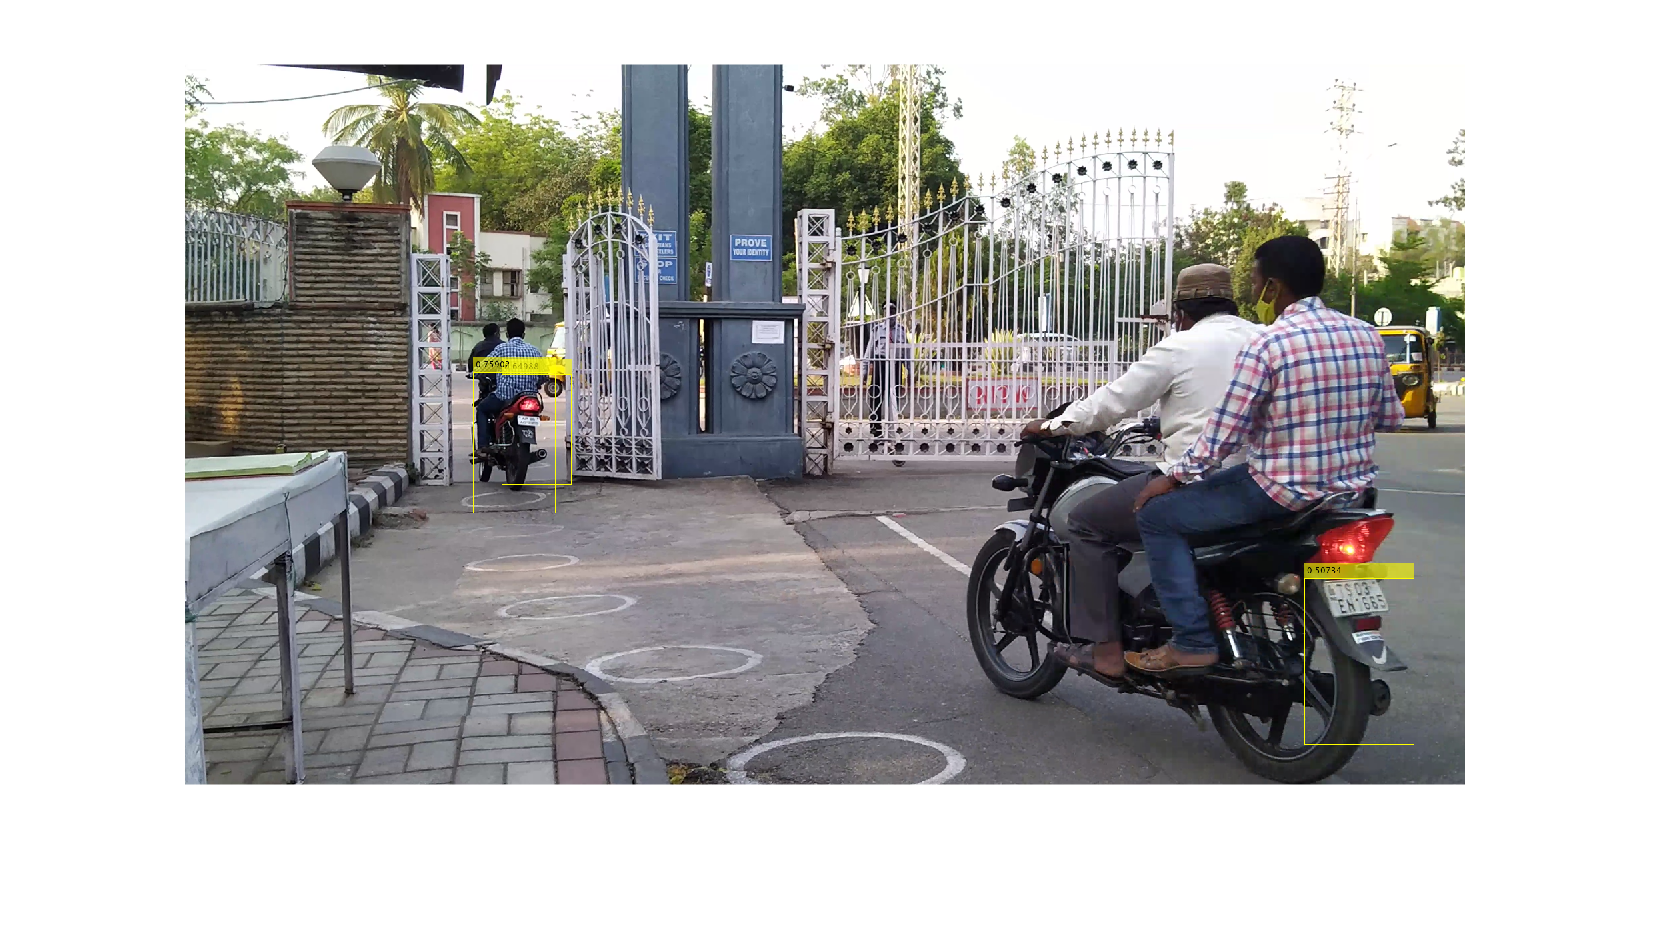

if(~isempty(bboxes))
  I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
end
figure
imshow(I)

gpuDevice(1)

ans =   CUDADevice with properties:

                      Name: 'GeForce GTX 1650'
                     Index: 1
         ComputeCapability: '7.5'
            SupportsDouble: 1
             DriverVersion: 11.2000
            ToolkitVersion: 10.1000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 4.2950e+09
           AvailableMemory: 3.2946e+09
       MultiprocessorCount: 14
              ClockRateKHz: 1515000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
            DeviceSelected: 1


Results = detect(detector1.detectorYolo2, testDatastore);

[ap,recall,precision] = evaluateDetectionPrecision(Results,testData(:,2:3));

recallv = cell2mat(recall);
precisionv = cell2mat(precision);
figure
plot(recallv,precisionv)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f',ap))